% Analytic Transfer function from Part 1
H = tf(K*[1 b1+d1 e1+(b1*d1)+c1 (b1*e1)+(c1*d1) c1*e1],[1 (d+b+a) (e+((b+a)*d)+c+(a*b)) (((b+a)*e)+((c+(a*b))*d)+(a*c)) (((c+(a*b))*e)+(a*c*d)) a*c*e])

H =
 
  0.03966 s^4 + 0.01302 s^3 + 0.9671 s^2 + 0.02907 s + 0.5071
  -----------------------------------------------------------
   s^5 + 0.5899 s^4 + 39.53 s^3 + 8.703 s^2 + 66.95 s + 8.37
 
Continuous-time transfer function.
Model Properties


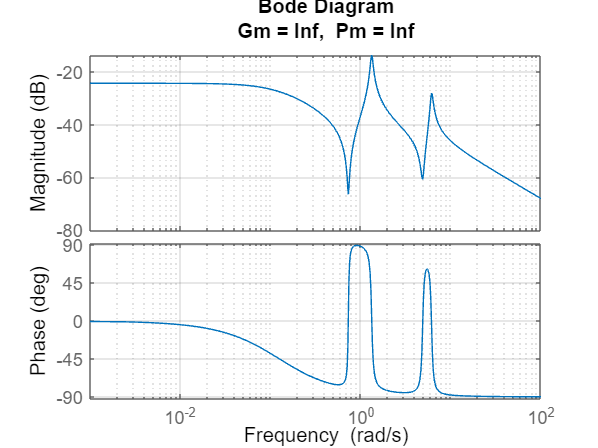


% Check the margins of H
margin(H)
grid on;


% The GM and PM are Inf.
% We have the target gain crossover frequency at 6.28 rad/sec.
% The Phase at 6.28 rad/sec is -40 deg. Phase margin calculation
% with this phase is 140 deg.
% We need to add positive gain to the compensator such that
% the magnitude plot crosses 0 dB at 6.28 rad/sec.

% As we need to shift the magnitude plot using some gain
% to have the gain crossover frequency at 1 Hz and not change
% the phase as the PM is already at least 40 deg, we check
% with just a proportional controller.

w_c = 2*pi*1; % crossover frequency at 1 Hz
mag_K_c = abs(squeeze(freqresp(H,w_c)));
K_c = 1/mag_K_c % gain required for target crossover frequency

K_c = 29.3132

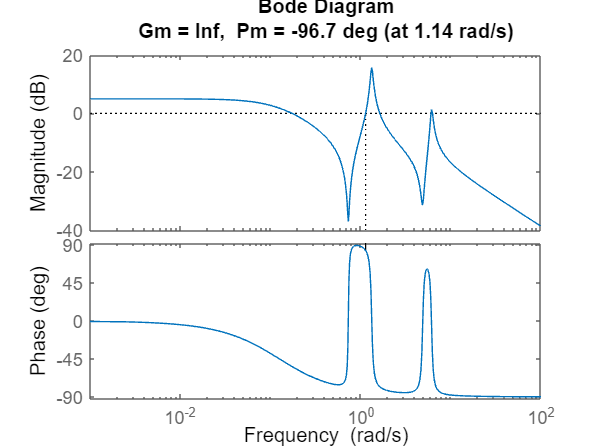


% Check margins without the compensator
margin(K_c * H)

[Gm_H, Pm_H, Wcg_H, Wcp_H] = margin(K_c * H)

Gm_H = Inf

Pm_H = -96.6922

Wcg_H = NaN

Wcp_H = 1.1383

% GM is still Inf. Negative PM shows that the system is unstable.
% We need a compensator that stabilizes the system.

% As we need to shift the magnitude plot up to set the gain
% crossover frequency at 1 Hz, we use a positive gain.
% We do not need to alter the phase right now, although
% we can reduce the phase by some amount. Main purpose
% of designing a compensator is to give positive gain for
% the magnitude plot to cross 0 dB.
% Hence, we choose a LAG COMPENSATOR for the same, as
% a Lead Compensator will add phase, which is the opposite
% of what we want to achieve.

s = tf('s');
w_c = 2*pi*1; % crossover frequency at 1 Hz

% Compensator Design
% Lag compensator (z > p)
% Lag compensator reduces the phase in this frequency range:
% w_start = 0.1*p to w_end = 10*z.
% Also, max phase lag occurs at: w = sqrt(z*p).

C1_lag = (s+62)/(s+0.636);
C_H_lag = C1_lag * H;
% Gain
mag_K_lag = abs(squeeze(freqresp(C_H_lag, w_c)));
K_lag = 1/mag_K_lag

K_lag = 2.9706

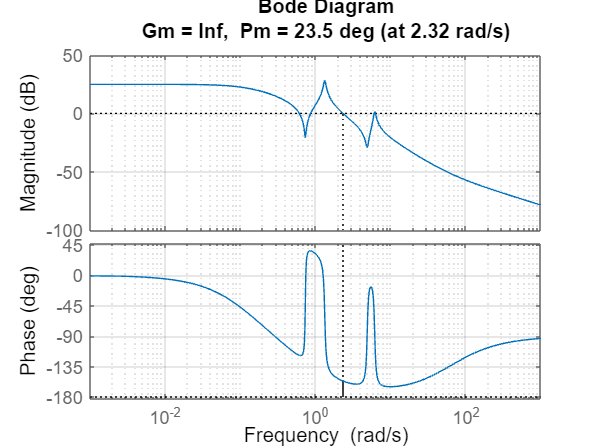

% Open Loop transfer function
L_lag = K_lag * C_H_lag;

% LEAD COMPENSATOR:
%phi = 25; % phase change required
%alpha = (1-sind(phi))/(1+sind(phi));
%tau = 1/(w_c*sqrt(alpha));
%C_lead = tf([tau 1], [alpha*tau 1]); % compensator transfer function
%C = K_c * C_lead; % Compensator Design
%L = C * H; % Open Loop transfer function

% Analyzing the margins
margin(L_lag)
grid on;

[Gm_lag, Pm_lag, Wcg_lag, Wcp_lag] = margin(L_lag)

Gm_lag = Inf

Pm_lag = 23.5168

Wcg_lag = NaN

Wcp_lag = 2.3205

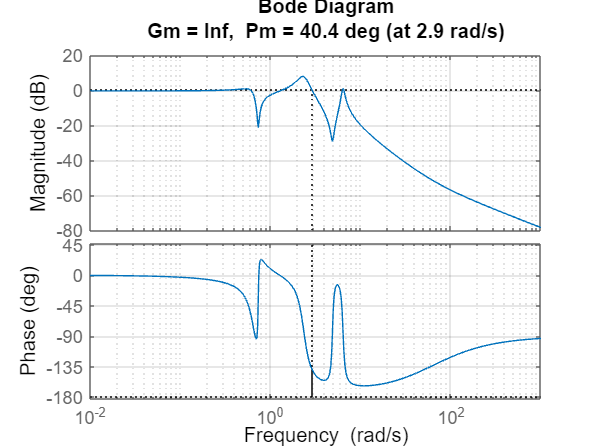


% Closed-loop system with compensator
T = feedback(L_lag, 1);
% Check the new margins and bandwidth with the compensator
margin(T)
grid on;

[bw] = bandwidth(T);
disp(['Closed-Loop Bandwidth: ', num2str(bw), 'Hz']);

Closed-Loop Bandwidth: 0.65684Hz



% We see from the above closed loop margin plot that
% PM for the closed loop system with the tuned lag
% compensator is 40.4 deg, perfect according to the
% requirements, and the Bandwidth is 0.656 Hz, which
% is closed enough to 1 Hz. But, the GM is still undefined.

% We choose to add another lag compensator that makes
% the phase plot go down at higher frequencies and potentially
% cross the -180 deg line and then tune that pole to achieve
% the required GM. We can see that there are 3 regions in the
% magnitude plot where the magnitude is below -10 dB:
% 1. w --> 0.7 - 0.8 rad/sec
% 2. w --> 3.7 - 5.7 rad/sec
% 3. w --> 7.4 rad/sec and beyond.
% If we observe these three regions in the phase plot, we can see
% that the first two regions have high phase values and opting
% them for reducing the phase below -180 deg is not a wise choice.
% Hence, the new lag compensator will focus on frequencies:
% w --> 7.4 - 20 rad/sec. We are choosing 20 rad/sec as the upper
% limit as the phase starts to increase beyond that frequency.

% Another Lag Compensators
s = tf('s');
C2_lag = (s+20)/(s+7.4);
% Maximum reduction in phase occurs at 12.165 rad/sec (sqrt(20*7.4)).
% Minimum required reduction in phase:
% 180 - phase at 12.165 rad/sec = 180 - 162 = 18 deg
% Expected reduction in phase:
% asind((z-p)/(z+p)) = 27.32 deg
% Hence, we can hope that this works!

C_total = C2_lag * C_H_lag;
% Gain
mag_K_lag_lag = abs(squeeze(freqresp(C_total, w_c)));
K_lag_lag = 1/mag_K_lag_lag

K_lag_lag = 1.3756

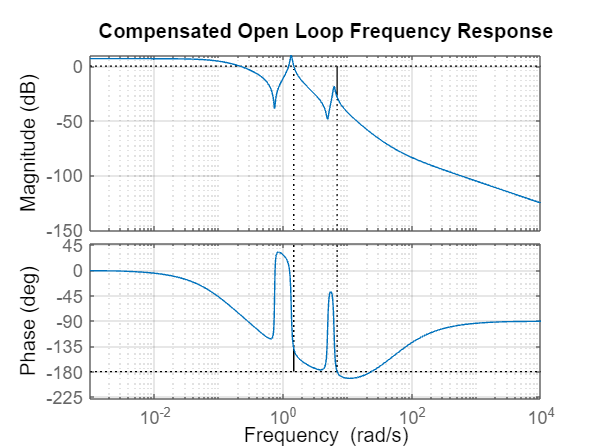

K_new = 0.1;
L_total = K_new * K_lag_lag * C_total;

% Analyzing the margins
margin(L_total)
title('Compensated Open Loop Frequency Response')
grid on;

[Gm_total, Pm_total, Wcg_total, Wcp_total] = margin(L_total)

Gm_total = 26.6109

Pm_total = 40.3021

Wcg_total = 6.8473

Wcp_total = 1.4563

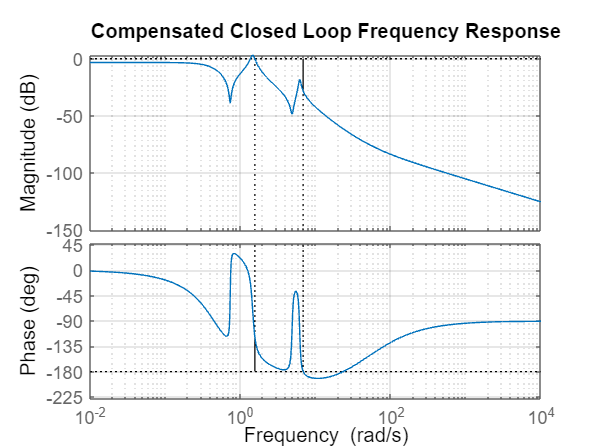


% Closed-loop system with compensator
T_total = feedback(L_total, 1);
% Check the new margins and bandwidth with the compensator
margin(T_total)
grid on;
title('Compensated Closed Loop Frequency Response')

[bw_total] = bandwidth(T_total);
disp(['Closed-Loop Bandwidth: ', num2str(bw_total), 'Hz']);

Closed-Loop Bandwidth: 0.3693Hz
